# Classification : LDA, SVM

clc; % clean command propmt
clear; % clean exist varaibles
close all; % close all figures.

### Load data

The built-in dataset named "fisheriris" are used in this practice.

This data contains sepal length, sepal width, petal length, petal width of the plant.

% Load fisheriris
data = importdata("fisheriris.mat")

data = 다음 필드를 포함한 struct :
    species: {150×1 cell}
       meas: [150×4 double]


% Remove one species to make it 2-class problem. 
% Original Data has 3 class(붓꽃의 종류) : setosa, versicolor, virginica 
unique(data.species)

ans = 3×1 cell 배열
    {'setosa'    }
    {'versicolor'}
    {'virginica' }


idx = ~strcmp(data.species,'setosa');

### Data Describtion - Select feature for training

X = data.meas(idx,3:4);     % feature : petal length, petal width
y = data.species(idx);      % class : species (versicolor, virginica)

Plot the data

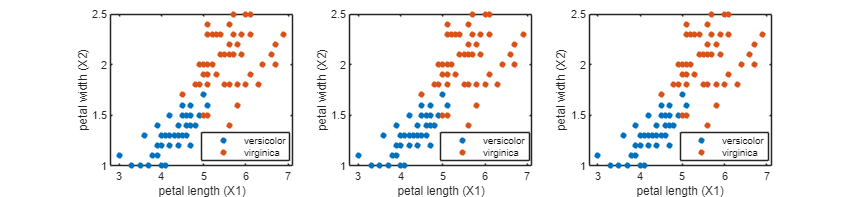

figure('Position',[10,10,1368,317]);
gscatter(X(:,1),X(:,2),y)

xlabel('petal length (X1)')
ylabel('petal width (X2)')
hold on

### Linear Discriminant Analysis (LDA)

"fitcdiscr: LDA 훈련 function

#### `!!!Fill the blank!!!`

% Train the LDA classifier
mdl_LDA = fitcdiscr(X,y);

% Extract the model information
W = mdl_LDA.Coeffs(2,1).Linear;  % Linear predictor coefficients
b = mdl_LDA.Coeffs(2,1).Const;  % Bias term

### Get the decision boundary(y(x) = 0) : y(x) = wTx + b

% LDA result : Plot the decision boundary
givenX1 = linspace(min(X(:,1)),max(X(:,1)),100); % Given X1.

Q: Given X1, how to get the expected X2 on the decision boundary?

y(x) = wTx + b = 0 if x is on the decision boundary.

#### `!!!Fill the blank!!!`

% b + w1*X1 + w2*X2 = 0
% X2 = -(b + W1*X1)/w2
% Hints: X2 = -(b + w1*X1)/w2
X2_LDA = -(b + W(1)*givenX1) ./ W(2);

Plotting the decision boundary

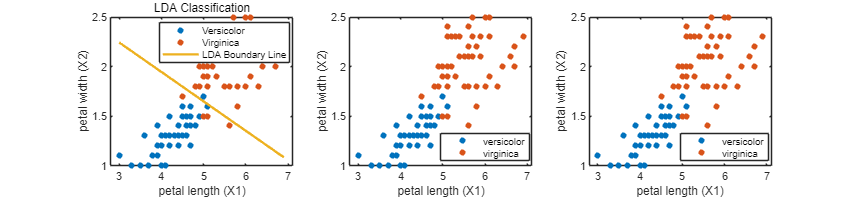

figure();
gscatter(X(:,1),X(:,2),y);
xlabel('petal length (X1)')
ylabel('petal width (X2)')
hold on

plot(givenX1, X2_LDA,'Linewidth',2);
legend('Versicolor','Virginica','LDA Boundary Line')
title('LDA Classification')

### Support Vector Machine (SVM)

"fitcsvm": SVM 훈련 function

#### `!!!Fill the blank!!!`

% Train the SVM classifier
% BoxConstraint(c) : hyperparameter (default = 1)
% Higher C - close to hard margin / lower C - close to soft margin
mdl_SVM = fitcsvm(X,y);           % Solver : 'SMO' (Default), 'L1QP' (Quadratic)

% Extract the model information
support_vector = mdl_SVM.SupportVectors; % Support vectors
W = mdl_SVM.Beta; % Linear predictor coefficients
b = mdl_SVM.Bias; % Bias term

Plotting samples

figure('Position',[10,10,1368,317]);
gscatter(X(:,1),X(:,2),y)
xlabel('petal length (X1)')
ylabel('petal width (X2)')
hold on

Plot the Hyperplane (~Decision boundary)

givenX = linspace(min(X(:,1)),max(X(:,1)),100);

#### `!!!Fill the blank!!!`

% b + b1*X1 + b2*X2 = 0
% X2 = -(b + b1*X1)/b2
% Hints: X2 = -(b + b1*X1)/b2
X2_SVM = -(b + W(1)*givenX) ./ W(2);

plot(givenX, X2_SVM,'Linewidth',2)     % Decision boundary
legend('Versicolor','Virginica','Support vectors','Alpha < 1', 'SVM Boundary Line')

Plot the Support Vectors

plot(support_vector(:,1), support_vector(:,2), 'ko', 'MarkerSize', 10);

C = mdl_SVM.BoxConstraints(1);    
realsv = find(mdl_SVM.Alpha < C);

plot(support_vector(realsv,1), support_vector(realsv,2), 'mo', 'MarkerSize', 10)
legend('Versicolor','Virginica','Support vectors','Alpha < 1')

Plot the Margin

m_width = 1/sqrt(W(1)^2+W(2)^2); % Margin half-width (Margin = 2/∣∣β‖)
X1margin_high = givenX+W(1)*m_width^2; % Shift the cordinate along with the orthogonal vector with a amplitude of m_width
X2margin_high = X2_SVM+W(2)*m_width^2;
X1margin_low = givenX-W(1)*m_width^2;
X2margin_low = X2_SVM-W(2)*m_width^2;
plot(X1margin_high,X2margin_high,'r--')
plot(X1margin_low,X2margin_low,'b--')

legend('Versicolor','Virginica','Support vectors','Alpha < 1', 'SVM Boundary Line' , ...
    'Upper Margin','Lower Margin')
title('SVM Classification')

**LDA & SVM Boundary Comparison **

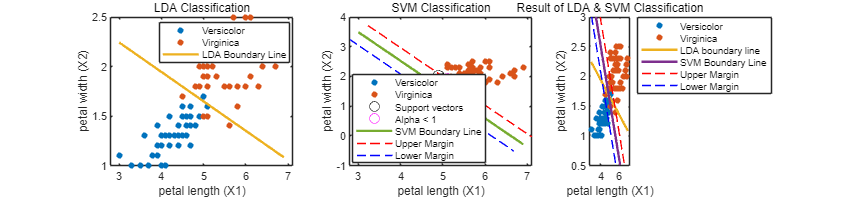

figure();
gscatter(X(:,1),X(:,2),y)
xlabel('petal length (X1)')
ylabel('petal width (X2)')
hold on

plot(givenX1,X2_LDA,'Linewidth',2)     % Decision boundary of LDA
plot(givenX,X2_SVM,'Linewidth',2)     % Decision boundary of SVM
plot(X1margin_high,X2margin_high,'r--')
plot(X1margin_low,X2margin_low,'b--')

% Plot setting
ylim([0.5 3]);
legend('Versicolor','Virginica', 'LDA boundary line', ...
    'SVM Boundary Line', 'Upper Margin','Lower Margin', ...
    'location','northeastoutside')
title('Result of LDA & SVM Classification')

### Performance Comparison with K-fold Cross Validation

close all;

**K-fold Cross Validation with LDA & SVM**

**Using the MATLAB function**

**with LDA**

LDAcv = crossval(mdl_LDA);

LDAcv =   ClassificationPartitionedModel
    CrossValidatedModel: 'Discriminant'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 100
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'versicolor'  'virginica'}
         ScoreTransform: 'none'


  Properties, Methods


lda_loss = kfoldLoss(LDAcv)

lda_loss = 0.0600

lda_acc = (1-lda_loss)*100;

lda_acc = 94

**with SVM**

SVMcv = crossval(mdl_SVM)

SVMcv =   ClassificationPartitionedModel
    CrossValidatedModel: 'SVM'
         PredictorNames: {'x1'  'x2'}
           ResponseName: 'Y'
        NumObservations: 100
                  KFold: 10
              Partition: [1×1 cvpartition]
             ClassNames: {'versicolor'  'virginica'}
         ScoreTransform: 'none'


  Properties, Methods


svm_loss = kfoldLoss(SVMcv)

svm_loss = 0.0500

svm_acc = (1-svm_loss)*100

svm_acc = 95

% Comparison with bar plot
figure;
bx = categorical({'LDA','SVM'});
by = [lda_acc svm_acc];
b = bar(bx,by,'FaceColor', 'flat');

% Higher one will be red
if by(1) > by(2)
    b.CData(1,:) = [0.8500 0.3250 0.0980]; % red
elseif by(1) < by(2)
    b.CData(2,:) = [0.8500 0.3250 0.0980];    
end

xlabel('Classification Methods')
ylabel('Mean Accuracy (%)')
title('K-fold crossvalidation')

% Make partition for K-fold cross validation
k = 5;
cv = cvpartition(y, 'KFold',k)

cv = K-겹 교차 검증 분할
   NumObservations: 100
       NumTestSets: 5
         TrainSize: 80  80  80  80  80
          TestSize: 20  20  20  20  20

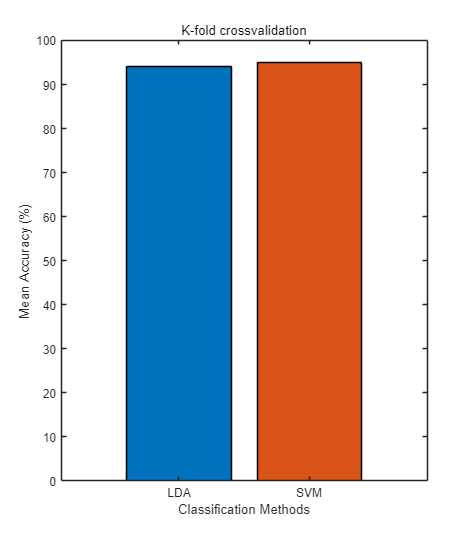

% Figure setting
fig1 = figure(1);
set(fig1,'Position',[10 10 525 600]);

fig2 = figure(2);
set(fig2,'Position',[600 10 525 600]);

% K-fold cross validation
for K = 1:5

    % indexing
    train_idx = training(cv, K);      % index of training samples
    train_dat = X(train_idx,:);
    train_label = y(train_idx);

    test_idx = test(cv,K);           % index of test samples
    test_dat = X(test_idx,:);
    test_label = y(test_idx);

#### `!!!Fill the blank!!!`

    % training    
    mdl_lda = fitcdiscr(train_dat,train_label);    % fit to LDA model
    mdl_svm = fitcsvm(train_dat,train_label);      % fit to SVM model

#### `!!!Fill the blank!!!`

    % test
    % Hint: use the function 'predict' 
    test_predict_lda = predict(mdl_lda, test_dat);   % predict the class with LDA model
    test_predict_svm = predict(mdl_svm, test_dat);   % predict the class with SVM model

    accuracy_lda(K) = mean(strcmp(test_predict_lda, test_label) );  % Accuracy of LDA
    accuracy_svm(K) = mean(strcmp(test_predict_svm, test_label) );  % Accuracy of SVM

    % confusion Matrix
    figure(1)
    subplot(3,2,K)
    confusionchart(test_predict_lda,test_label)
    xlabel('Predicted class')
    ylabel('True class')
    title(['Accuracy = ' num2str(accuracy_lda(K)*100) '%'])
    
    figure(2)
    subplot(3,2,K)
    confusionchart(test_predict_svm,test_label)
    xlabel('Predicted class')
    ylabel('True class')
    title(['Accuracy = ' num2str(accuracy_svm(K)*100) '%'])
end

figure(1)
s1 = subplot(3,2,6);
ACC_mean_lda = mean(accuracy_lda)*100  % Mean accuracy of LDA
text(0, 0.5, ['Mean Accuracy = ' num2str(ACC_mean_lda) '%'])
set(s1, 'visible', 'off')
sgtitle('LDA Confusion Matrix')

figure(2)
s2 = subplot(3,2,6);
ACC_mean_svm = mean(accuracy_svm)*100  % Mean accuracy of SVM
text(0, 0.5, ['Mean Accuracy = ' num2str(ACC_mean_svm) '%'])
set(s2, 'visible', 'off')
sgtitle('SVM Confusion Matrix')

연산자 사용이 유효하지 않습니다.